# Estimation

clc;clear
load("data.mat")
wFL = whlSpdFL;
wFR = whlSpdFR;
wRL = whlSpdRL;
wRR = whlSpdRR;

STEER_GEAR_RATIO = 16;
TRACK_WIDTH = 1.65;
lf = 1.47;
lr = 1.51;
h = 0.65;
NORMAL_RAIDUS = 0.36;
M = 2556;
g = 9.81;

WA = SWA/STEER_GEAR_RATIO;

## Task1: Wheel hub speed

 Compute the four wheel hub translational speeds $v_x$ relative to ground as a function of time. $v_{xwi}, i=FL,FR,RL,RR$

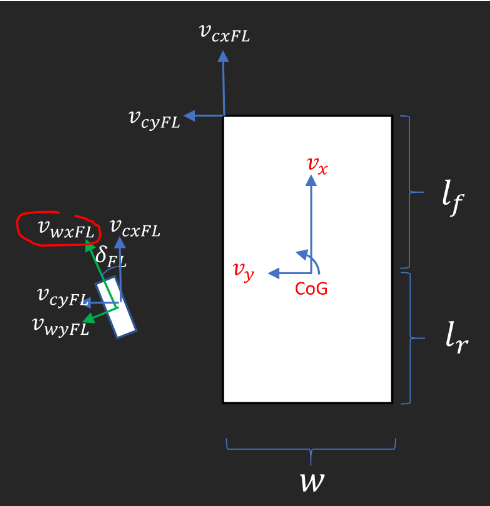

Trivial solution


$$v_{wx}=\omega*\hat{r}$$


But should also investigate if it is possible to account for the effect of longitudinal slip.

Compensate for wheel slip. $C_{nx}=40 \ N/N$. Assume normal force $F_{iz}
$ is static normal load

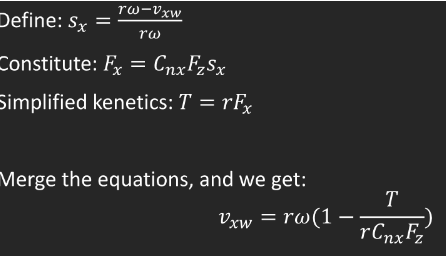

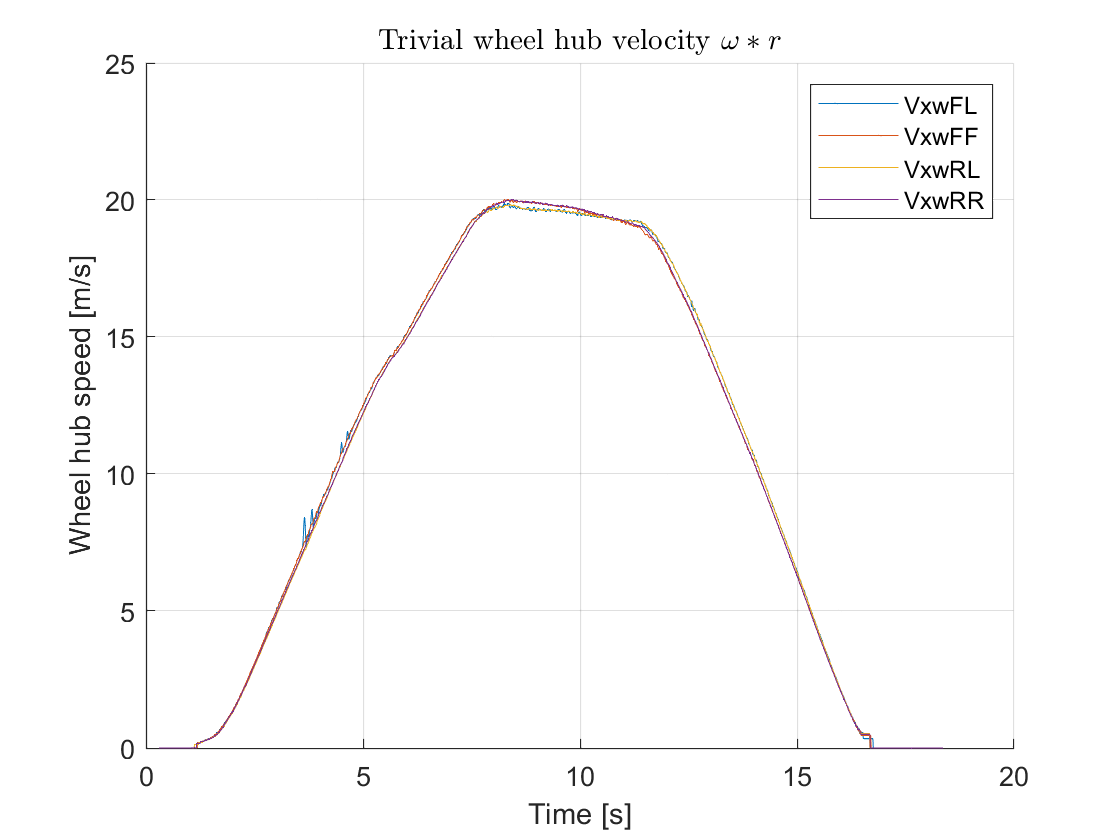

% normalized tire stiffness
Cnx = 40;
% trivial wheel hub speed
% w*r
triVxwFL = wFL * NORMAL_RAIDUS;
triVxwFR = wFR * NORMAL_RAIDUS;
triVxwRL = wRL * NORMAL_RAIDUS;
triVxwRR = wRR * NORMAL_RAIDUS;

figure
hold on
grid on
plot(Time, triVxwFL)
plot(Time, triVxwFR)
plot(Time, triVxwRL)
plot(Time, triVxwRR)
xlabel('Time [s]')
ylabel('Wheel hub speed [m/s]')
legend('VxwFL', 'VxwFF','VxwRL','VxwRR')
title('Trivial wheel hub velocity $\omega*r$','Interpreter','latex')

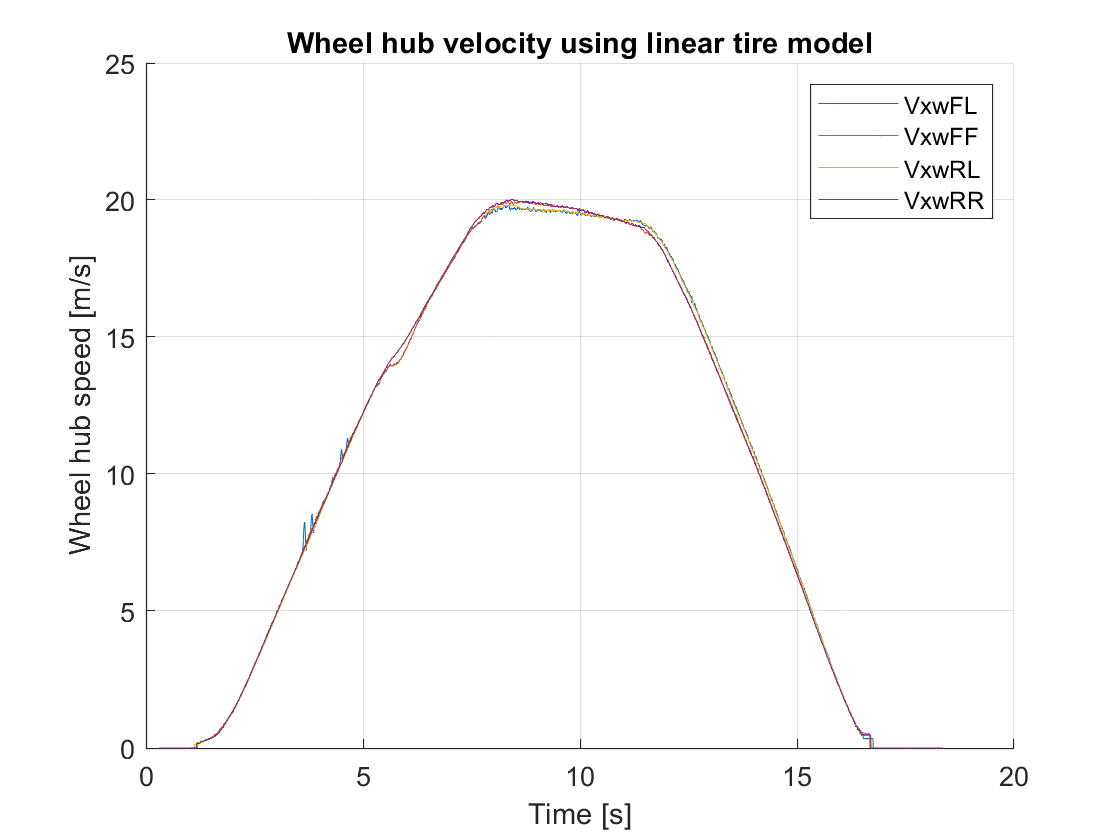

% account for longitudinal tire slip
FzFL = M*g/4;
FzFR = M*g/4;
FzRL = M*g/4;
FzRR = M*g/4;

VxwFL = wFL .* NORMAL_RAIDUS .* (1-(TpFL-TbFL)/(NORMAL_RAIDUS *Cnx * FzFL));
VxwFR = wFR .* NORMAL_RAIDUS .* (1-(TpFR-TbFR)/(NORMAL_RAIDUS *Cnx * FzFR));
VxwRL = wRL .* NORMAL_RAIDUS .* (1-(TpRL-TbRL)/(NORMAL_RAIDUS *Cnx * FzRL));
VxwRR = wRR .* NORMAL_RAIDUS .* (1-(TpRR-TbRR)/(NORMAL_RAIDUS *Cnx * FzRR));

figure
hold on
grid on
plot(Time, VxwFL)
plot(Time, VxwFR)
plot(Time, VxwRL)
plot(Time, VxwRR)
xlabel('Time [s]')
ylabel('Wheel hub speed [m/s]')
legend('VxwFL', 'VxwFF','VxwRL','VxwRR')
title('Wheel hub velocity using linear tire model')

## Task 2: Transformation to CoG

Project each hub speed $v_{xwi}$ to COG

From Vxwi to COG

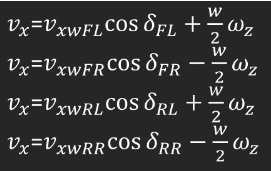

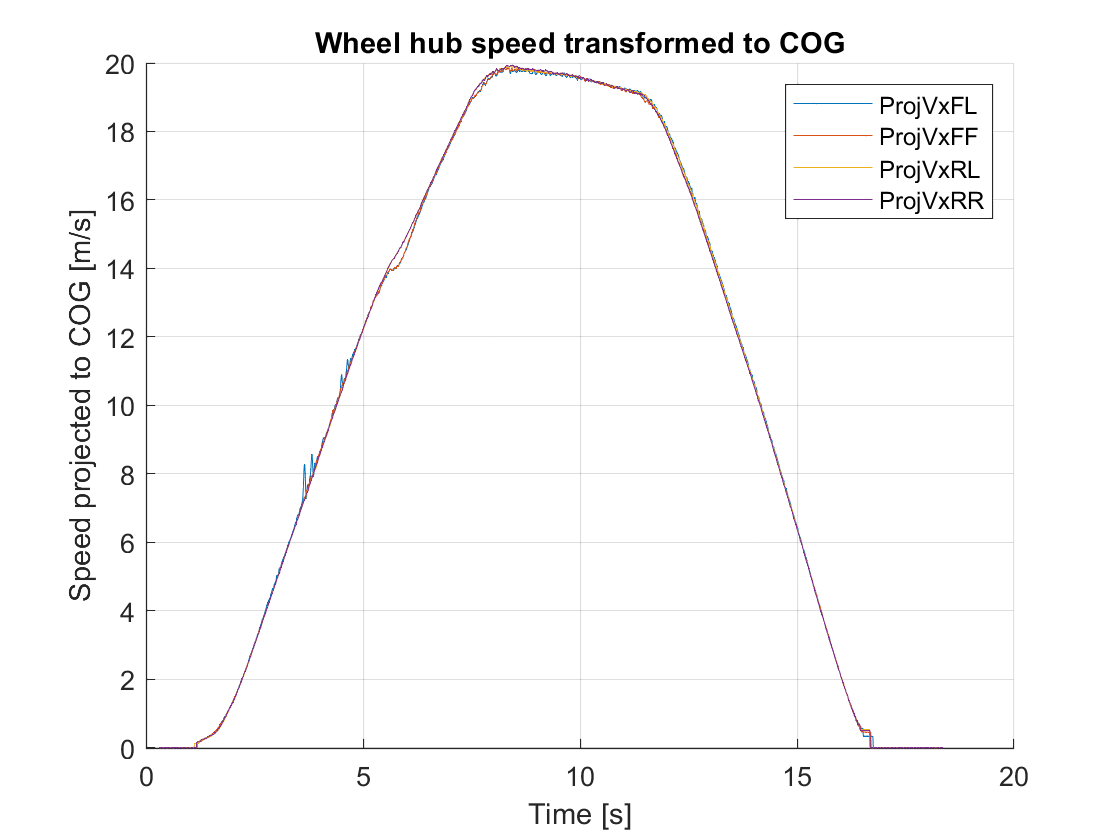

ProjVxFL = VxwFL .* cos(WA) + TRACK_WIDTH/2 .* wz;
ProjVxFR = VxwFR .* cos(WA) - TRACK_WIDTH/2 .* wz;
ProjVxRL = VxwRL .* cos(0) + TRACK_WIDTH/2 .* wz;
ProjVxRR = VxwRR .* cos(0) - TRACK_WIDTH/2 .* wz;

figure
hold on
grid on
plot(Time, ProjVxFL)
plot(Time, ProjVxFR)
plot(Time, ProjVxRL)
plot(Time, ProjVxRR)
xlabel('Time [s]')
ylabel('Speed projected to COG [m/s]')
legend('ProjVxFL', 'ProjVxFF','ProjVxRL','ProjVxRR')
title('Wheel hub speed transformed to COG')

## Task 3: Selection of the best projected vehicle speed

Design an algorithm that selects and switches to one among the four vehicle speed over ground  signals from task 2. 

The algorithm should at each  time sample select the vehicle speed that has the highest quote of tyre normal load and wheel  torque

$abs(\frac{F_{zi}}{T_i})$. Compute the rms error of the nominal estimated vehicle speed over ground (with  the ground truth as the reference)

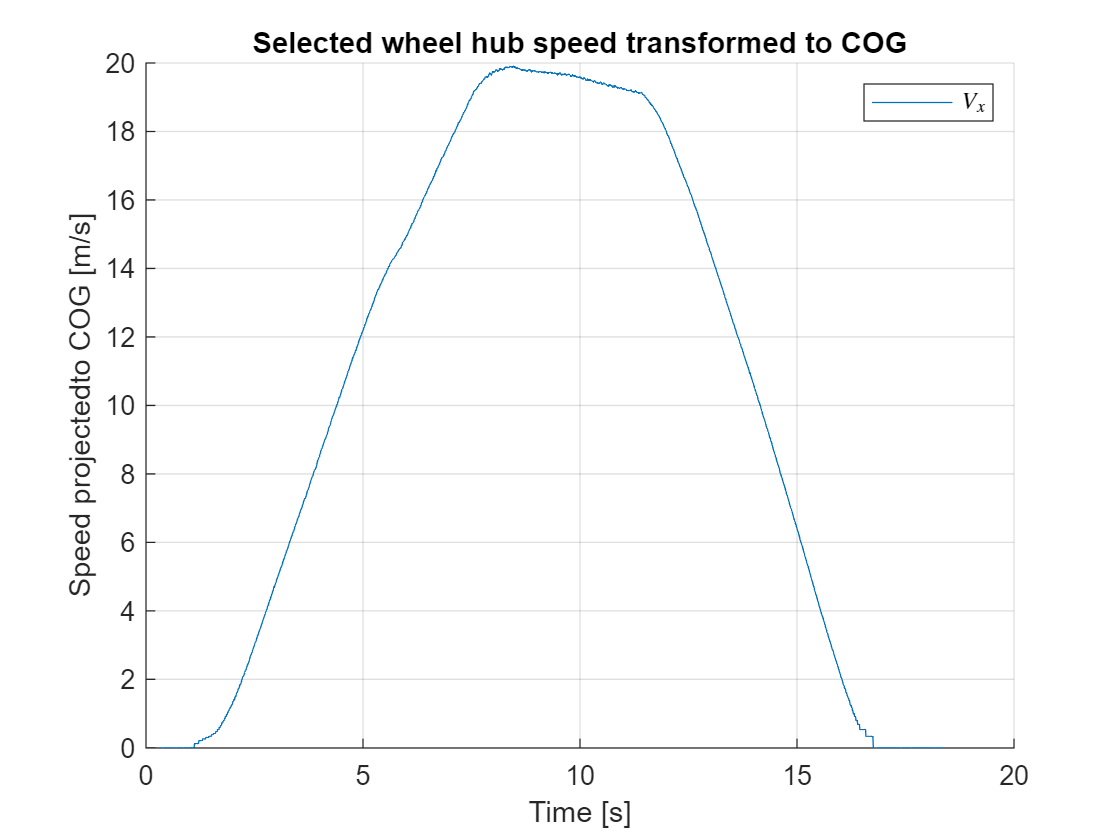

% 1 2 3 4 ...
% 5 6 7 8 ...
% 2 2 3 3 ...
% 4 4 3 3 ...
allVxs = [ProjVxFL, ProjVxFR, ProjVxRL, ProjVxRR];
allVxs = allVxs';
database = [abs(FzFL./(TpFL-TbFL)), abs(FzFR./(TpFR-TbFR)), abs(FzFR./(TpRL-TbRL)), abs(FzRR./(TpRR-TbRR))];
database = database';
[~,idxs] = max(database , [], 1);

linear_idx = sub2ind(size(allVxs), idxs, 1:numel(idxs));
selectedVx = allVxs(linear_idx);
figure
hold on
grid on
plot(Time, selectedVx)
xlabel('Time [s]')
ylabel('Speed projectedto COG [m/s]')
legend('$V_x$','Interpreter','latex')
title('Selected wheel hub speed transformed to COG')

errors = selectedVx - Vx_true';
RMS = rms(errors);
disp('rms error of the nominal estimated vehicle speed over ground is: ')

rms error of the nominal estimated vehicle speed over ground is: 


disp(RMS)

    0.2552



## Task 4: Uncertainty 